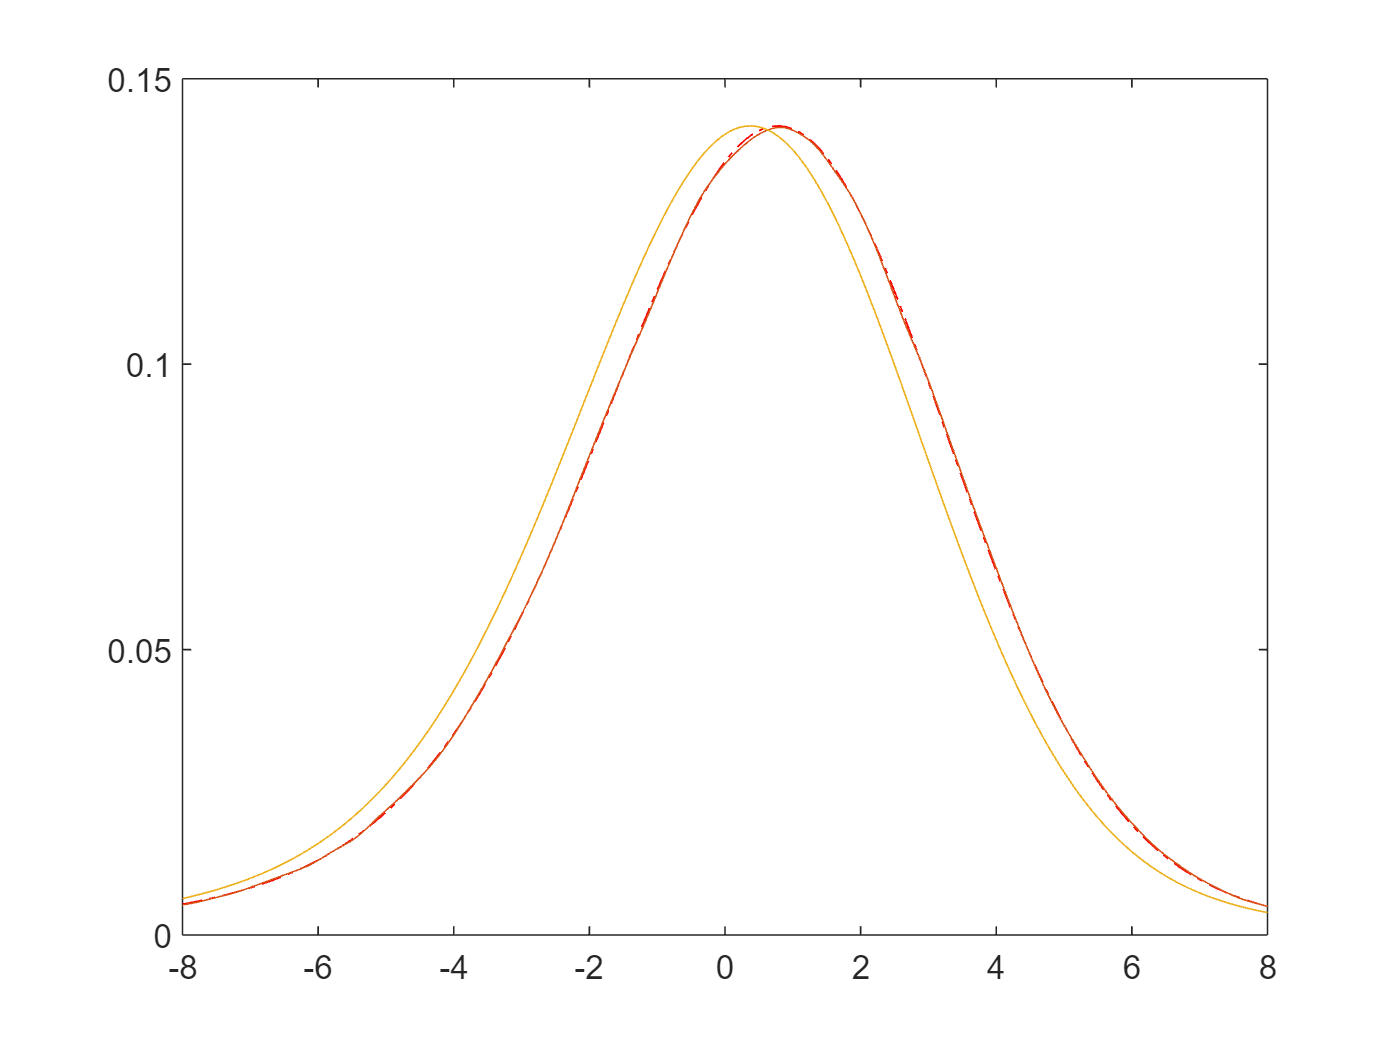

x1_1=-8:.1:8;
pdf1=asymstab(x1_1,1.7,-0.4,2,0.3);

pd2= makedist('Stable',alpha=1.7,beta=-0.4,gam=2,delta=0.3);
pdf2 = pdf(pd2,x1_1);

x1_2=stabgen(1000000,1.7,-0.4,2,0.3,1);
int1=(max(x1_2)-min(x1_2))/1000000;
[f1,xi1]=ksdensity(x1_2,(min(x1_2):int1:max(x1_2)),'Function','pdf');


figure
plot(x1_1,pdf1,'r-.');
hold on;
plot(xi1,f1);
plot(x1_1,pdf2);
xlim([-8 8]);
hold off;

pdf2 = sum_asymstab(x1_1,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3);
pdf3 = asymstab(x1_1,1.7,-0.424,2.34,-0.2);

x2_2=sum_stabgen(1000000,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3,1,2);
x2_2_1=stabgen(1000000,1.7,-0.4,2,-0.5,1);
x2_2_2=stabgen(1000000,1.7,-0.5,1,0.3,2);
int2=(max(x2_2)-min(x2_2))/1000000;
[f2,xi2]=ksdensity(x2_2,(min(x2_2):int2:max(x2_2)),'Function','pdf');
int2_1=(max(x2_2_1)-min(x2_2_1))/1000000;
[f2_1,xi2_1]=ksdensity(x2_2_1,(min(x2_2_1):int2_1:max(x2_2_1)),'Function','pdf');
int2_2=(max(x2_2_2)-min(x2_2_2))/1000000;
[f2_2,xi2_2]=ksdensity(x2_2_2,(min(x2_2_2):int2_2:max(x2_2_2)),'Function','pdf');
figure
plot(x1_1,pdf2,'r-.');
hold on;
plot(xi2,f2);
plot(x1_1,pdf3,'b-');
xlim([-8 8]);
hold on;
plot(xi2_1,f2_1);
hold on;
plot(xi2_2,f2_2);
hold off;